# Problem 3

## Toy Dataset IV

n = 200;
x = 3 * (rand(n, 4) - 0.5);
y = (2 * x(:, 1) - 1 * x(:,2) + 0.5 + 0.5 * randn(n, 1)) > 0;
y = 2 * y -1;

x = x';
y = y';

k_row = y.*x;
K = k_row' * k_row;
lambda = 3.3;
eta = @(t) 1./(lambda * t);
ndLf = @(a) (-1/(4*lambda)) .* (a' * K * a) + a'*ones(size(a));
nab_ndLf = @(a) (1/(2*lambda)) .* (K * a) - ones(size(a));
w_original = @(alpha) (1/(2*lambda)).*(alpha .* y')' * x';
Loss_original = @(w) sum(max(0,1-y.*(w*x))) + lambda .* (w*w');
proj = @(a) min(1,max(0,a)); % projection to [0,1]

### minimize the negative dual Lagrange function

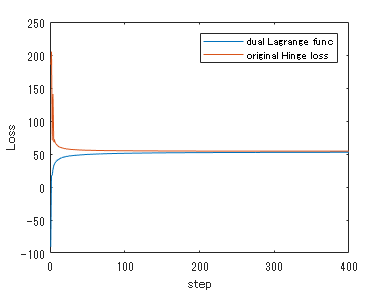

alpha = zeros(n,1);
step = 400;
w_history = zeros(step,4);
Loss_original_history = zeros(step,1);
Loss_dual_history = zeros(step,1);
for t =1:step
    eta_t = eta(t);

    alpha = arrayfun(proj, (alpha - eta_t .* nab_ndLf(alpha)));
    w_history(t,:) = w_original(alpha);
    Loss_original_history(t,:) = Loss_original(w_history(t,:));
    Loss_dual_history(t,:) = ndLf(alpha);
end
time= 1:step;
plot(time,Loss_dual_history);
hold on
plot(time, Loss_original_history);
legend('dual Lagrange func','original Hinge loss');
xlabel('step');
ylabel('Loss');
hold off

fprintf("The duality gap, %.8f",Loss_original_history(t,:)-Loss_dual_history(t,:))

The duality gap, 1.73562191